# SVM: non-linearly vs lineary separable sets

*© *Copyright 2022 The MathWorks, Inc

## Random dataset with non linearly separable classes in $R^2$

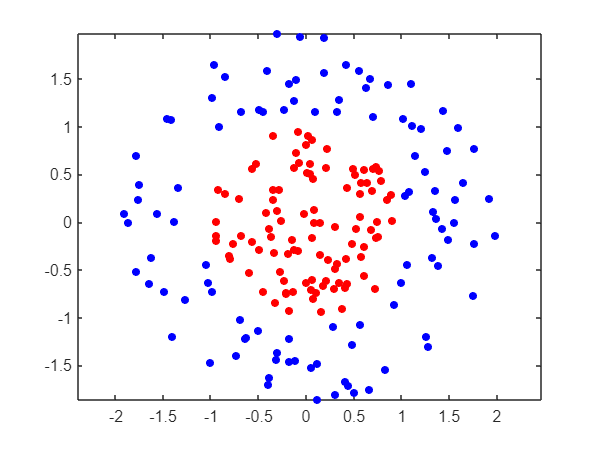

r = sqrt(rand(100 ,1));                         % random radius
t = 2*pi*rand(100 ,1);                          % random angle
data1 = [r.* cos(t), r.* sin(t)];               % points of class -1 (RED)

r2 = sqrt(3*rand(100 ,1) +1);                   % random radius for blue ring
t2 = 2* pi*rand (100,1);                        % random angle for blue ring
data2 = [r2 .* cos(t2), r2 .* sin(t2)];         % points of class +1 ( BLUE )

data3  = [data1; data2];                        % merge data together
theclass = ones(200,1);                         % assign class +1
theclass(1:100) = -1;                           % assign class -1

figure
plot(data1(:,1), data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1), data2(:,2),'b.','MarkerSize',15)
axis equal
hold off

Data become linearly separable in a higher dimensional space:


$$\varphi :R^{2\;} \longrightarrow R^3 :\;\left(x,y\right)\longmapsto \left(x,y,x^2 +y^2 \right)$$


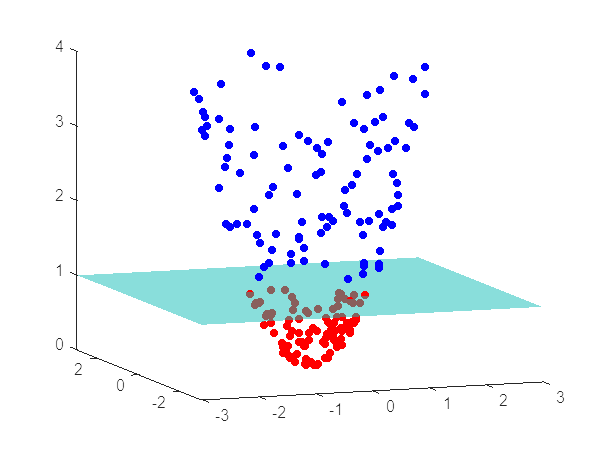

x = data3(:,1);
y = data3(:,2);
z = x.^2 + y.^2;
figure
plot3(x(1:100), y(1:100), z(1:100),'r.','MarkerSize',15 )
hold on
plot3(x(101:end), y(101:end), z(101:end),'b.','MarkerSize',15 )
[PLANE1, PLANE2] = meshgrid(-3:0.1:3);
surf(PLANE1, PLANE2, ones(size(PLANE1)))
shading interp, alpha 0.5
view([-20 10])

Another way to map data in a higher dimensional space to gain linear separability


$$\varphi :R^{2\;} \longrightarrow R^3 :\;\left(x,y\right)\longmapsto \left(x^2 ,\sqrt{2}\textrm{xy},y^2 \right)$$


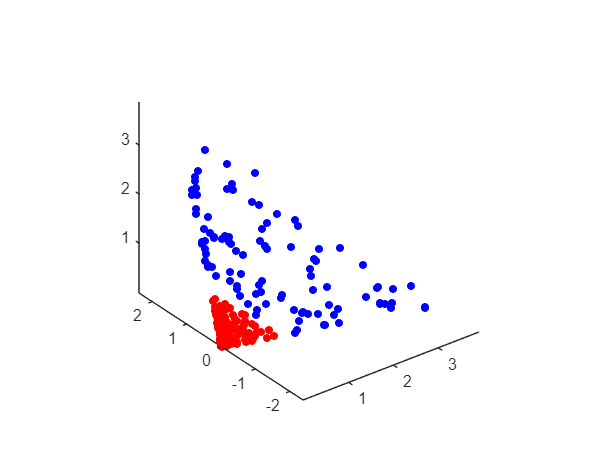

w1 = x.^2;
w2 = sqrt(2).*x.*y;
w3 = y.^2;
figure
plot3(w1(1:100), w2(1:100), w3(1:100),'r.','MarkerSize',15 )
hold on
plot3(w1(101:end), w2(101:end), w3(101:end),'b.','MarkerSize',15 )
axis equal